% Liczba ramek do wczytania (przy 10 sekundach i 30 FPS będzie to 300)
N = 600;

% wektor jasności
br = zeros(3, N);

use_video = 1;

if use_video
    % wczytywanie pliku wideo do analizy
    v = VideoReader(['IMG_5844.mp4']);
else
    % lista obrazów do analizy
    imds = imageDatastore('./data/', 'FileExtension', '.jpg');
end

% wczytanie pierwszych N obrazów i analiza jasności
for i=1:N

    if use_video
        % dla pliku wideo ładowanie ramki z otwartego źródła
        I = read(v,i);
    else
        % wczytujemy obraz
        I = imread(imds.Files{i});
    end

    h = size(I,1);
    w = size(I,2);

    % wybieramy jedynie czerwoną składową obrazu
    I = I(:,:,1);

    % jasność punktu na środku obrazu
    br(1, i) = I(h/2, w/2);

    % wyznaczamy średnią z całego obrazu
    br(2, i) = mean(I, 'all');
end

% dla ułatwienia późniejszej analizy od razu można odjąć od sygnału składową stałą
br = br - mean(br, 2);

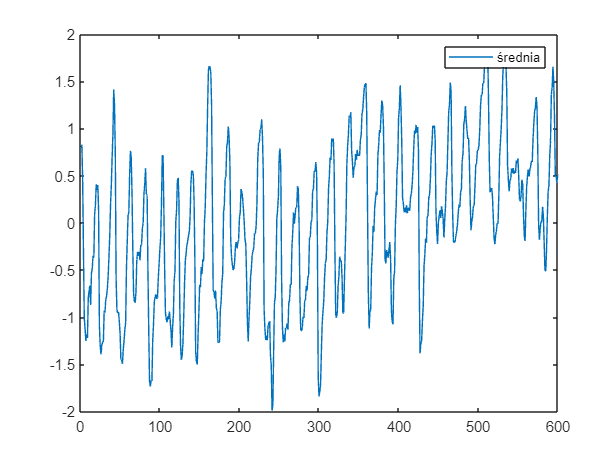

sig = br(2,:);
figure
plot(br(2,:));
legend('średnia');

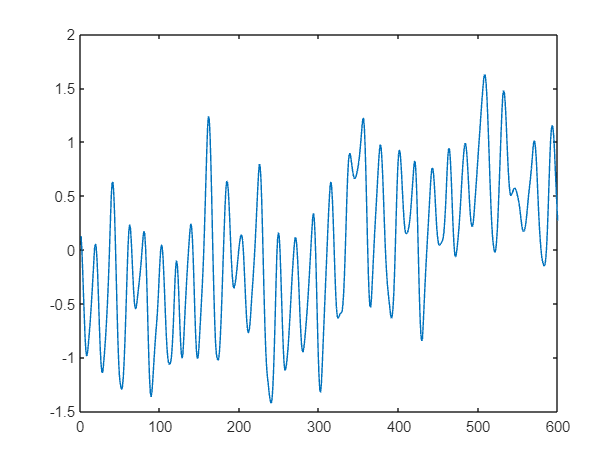

g5 = fspecial('gaussian', [1, 10], 3);
cg5 = conv(sig, g5, 'same');
plot(cg5)

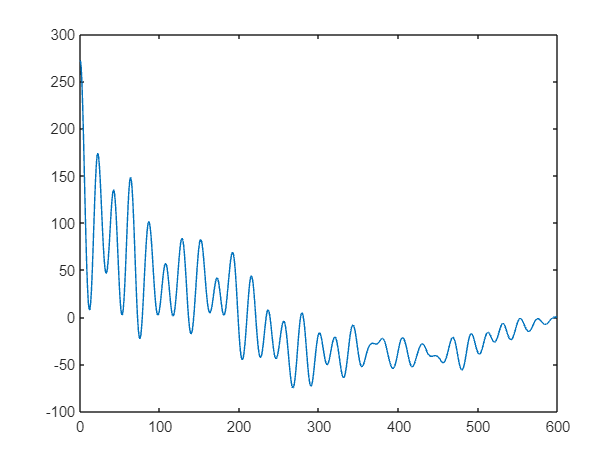

[r1, lags] = xcorr(cg5);
r1 = r1(lags >= 0);
lags = lags(lags>=0);

figure;
plot(lags, r1);

[pks, loc] = findpeaks(r1, "MinPeakDistance", 10, "MinPeakProminence", 20);
fs = 30;

% przesunięcie w sekundach
lag_s = loc(12) * 1 / 12 /fs;

% częstotliwość bazowa
freq = 1/lag_s

freq = 1.4008


BPM = freq * 60

BPM = 84.0467